# Free fermions in Gibbs and microcanonical ensembles

r = 1; % separation <c_i^+ c_(r+i)>

N = 12;

kk = -(N-1)/N*pi:2*pi/N:(N-1)*pi/N;
eps = 1-1*cos(kk);

TT = linspace(4.9,5.1, 20);
Cgibbs = zeros(1, length(TT));

EE = linspace(-max(eps),max(eps),40);
FD = zeros(1, length(EE));
T = TT(3)

T = 4.9211

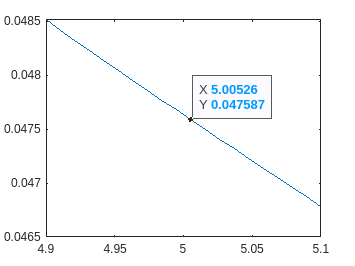

FDstats = @(E) 1/(exp(E/T)+1);

for i = 1:length(EE)
    FD(i) = FDstats(EE(i));
end
%plot(EE, FD)


% correlation using the Gibbs ensemble
for i = 1:length(TT)
    corr = exp(-1i*kk*r).*1./(exp(eps/TT(i))+1);
    Cgibbs(i) = real(sum(corr)/N);
end
plot(TT,Cgibbs)

Sampling from microcanonical ensemble.

% the relation between temperature and energy density
TT = linspace(0, 0.1, 20)

TT =          0    0.0053    0.0105    0.0158    0.0211    0.0263    0.0316    0.0368    0.0421    0.0474    0.0526    0.0579    0.0632    0.0684    0.0737    0.0789    0.0842    0.0895    0.0947    0.1000


ee = zeros(1, length(TT))

ee =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


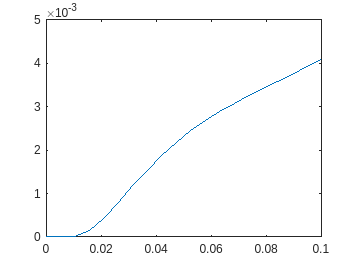

for i = 1:length(TT)
    ee(i) = sum(eps./(exp(eps/TT(i))+1))/N;
end
plot(TT, ee)


% constructing the microcanonical ensemble
% strict partition numbers
N = 20;
kk = -(N-1)/N*pi:2*pi/N:(N-1)*pi/N;
eps = 2-2*cos(kk);
bitstrs = cell(2^N, 1);
for i = 0:2^N-1
    bstr = dec2bin(i, N);
    bvec = double(bstr) - '0';
    bitstrs{i+1} = bvec;
end

r = 1;
mc = [];

% calculate the energy window, E(beta)
T = 4;
E = sum(eps.*1./(exp(eps/T)+1))

E = 12.9212




% check whether the configuration is in the energy window
delta = 0.1; % the one-sided energy window, E \in [E-delta,E+delta]
for i = 1:length(bitstrs)
    occ = bitstrs{i};
    Ei = sum(eps(occ==1));
    if abs(E-Ei) < delta
        mc = [mc; occ];
    end
end

% calculate the correlation function of the MC ensemble
Cmc = real(sum(exp(-1i*kk*r) .* sum(mc, 1)/size(mc, 1)))

Cmc = 1.2432

corr = real(sum(exp(-1i*kk*r).*1./(exp(eps/T)+1)))

corr = 1.1602

% The energy spectrum

mc =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     1     1     1     0     1
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     1     1     0     1     1
     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     0     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     1     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     1     1     1     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     1     0     1     1
     0     0     0     0   


k = linspace(-pi, pi, 200);
h = 1 - cos(k);
N = 20;















